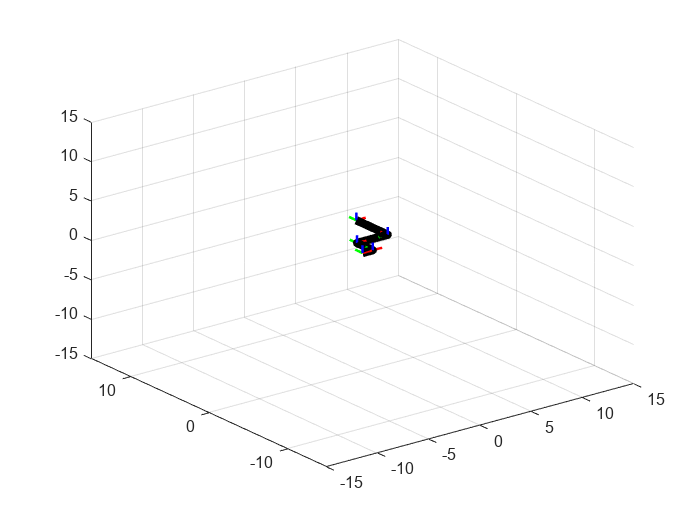

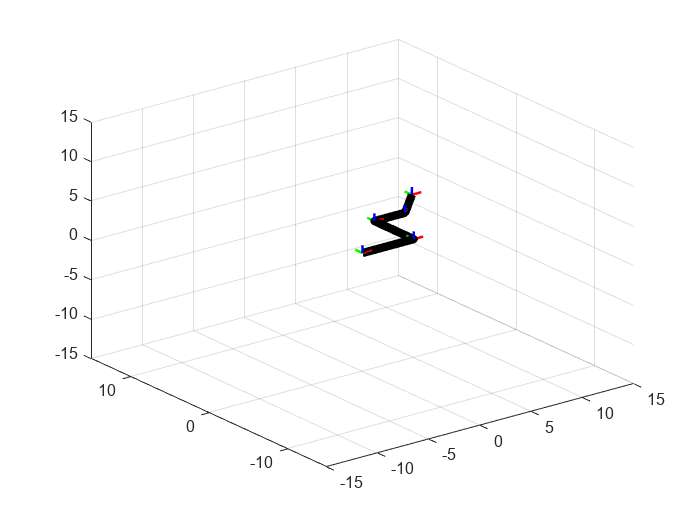

q1 = linspace(1, 5, 100);
q2 = linspace(2, 5, 100);
q3 = linspace(pi/2, pi/4, 100);
l1 = 3;
l2 = 4;

figure;
axis([-8 8 -8 8 -8 8]);

for i = 1:numel(q1)
    T01 = [1, 0, 0, q1(i);
           0, 1, 0, 0;
           0, 0, 1, 0;
           0, 0, 0, 1]; % X translatie
    
    T12 = [1, 0, 0, 0;
           0, 1, 0, q2(i);
           0, 0, 1, 0;
           0, 0, 0, 1]; % Y translatie
    
    T23 = [cos(q3(i)), -sin(q3(i)), 0, l1;
           sin(q3(i)), cos(q3(i)), 0, 0;
           0, 0, 1, 0;
           0, 0, 0, 1]; % Z rotatie
    
    T3e = [1, 0, 0, l2;
           0, 1, 0, 0;
           0, 0, 1, 0;
           0, 0, 0, 1]; % efector
    
    P0 = [0; 0; 0; 1];
    P1 = T01 * P0;
    P2 = T01 * T12 * P0;
    P3 = T01 * T12 * T23 * P0;
    Pe = T01 * T12 * T23 * T3e * P0;

    pozitie_robot = [P0, P1, P2, P3, Pe];

    plot3(pozitie_robot(1,:), pozitie_robot(2,:), pozitie_robot(3,:), 'Color', 'k', 'LineWidth', 5);
    axis([-8 8 -8 8 -8 8]);

    xlim([-15,15]);
    ylim([-15,15]);
    zlim([-15,15]);
    
    % Adăugarea săgeților pentru fiecare cuplă
    hold on;
    quiver3(P0(1), P0(2), P0(3), T01(1,1), T01(2,1), T01(3,1), 'r', 'LineWidth', 1.5); % Axele X pentru prima cuplă
    quiver3(P0(1), P0(2), P0(3), T01(1,2), T01(2,2), T01(3,2), 'g', 'LineWidth', 1.5); % Axele Y pentru prima cuplă
    quiver3(P0(1), P0(2), P0(3), T01(1,3), T01(2,3), T01(3,3), 'b', 'LineWidth', 1.5); % Axele Z pentru prima cuplă
    
    quiver3(P1(1), P1(2), P1(3), T12(1,1), T12(2,1), T12(3,1), 'r', 'LineWidth', 1.5); % Axele X pentru a doua cuplă
    quiver3(P1(1), P1(2), P1(3), T12(1,2), T12(2,2), T12(3,2), 'g', 'LineWidth', 1.5); % Axele Y pentru a doua cuplă
    quiver3(P1(1), P1(2), P1(3), T12(1,3), T12(2,3), T12(3,3), 'b', 'LineWidth', 1.5); % Axele Z pentru a doua cuplă

    quiver3(P2(1), P2(2), P2(3), T12(1,1), T12(2,1), T12(3,1), 'r', 'LineWidth', 1.5); % Axele X pentru a doua cuplă
    quiver3(P2(1), P2(2), P2(3), T12(1,2), T12(2,2), T12(3,2), 'g', 'LineWidth', 1.5); % Axele Y pentru a doua cuplă
    quiver3(P2(1), P2(2), P2(3), T12(1,3), T12(2,3), T12(3,3), 'b', 'LineWidth', 1.5); % Axele Z pentru a doua cuplă
    
    quiver3(P3(1), P3(2), P3(3), T23(1,1), T23(2,1), T23(3,1), 'r', 'LineWidth', 1.5); % Axele X pentru a treia cuplă
    quiver3(P3(1), P3(2), P3(3), T23(1,2), T23(2,2), T23(3,2), 'g', 'LineWidth', 1.5); % Axele Y pentru a treia cuplă
    quiver3(P3(1), P3(2), P3(3), T23(1,3), T23(2,3), T23(3,3), 'b', 'LineWidth', 1.5); % Axele Z pentru a treia cuplă
    
    quiver3(Pe(1), Pe(2), Pe(3), T3e(1,1), T3e(2,1), T3e(3,1), 'r', 'LineWidth', 1.5); % Axele X pentru efector
    quiver3(Pe(1), Pe(2), Pe(3), T3e(1,2), T3e(2,2), T3e(3,2), 'g', 'LineWidth', 1.5); % Axele Y pentru efector
    quiver3(Pe(1), Pe(2), Pe(3), T3e(1,3), T3e(2,3), T3e(3,3), 'b', 'LineWidth', 1.5); % Axele Z pentru efector
    
    grid on;
    hold off;
    drawnow
    pause(0.05);
end